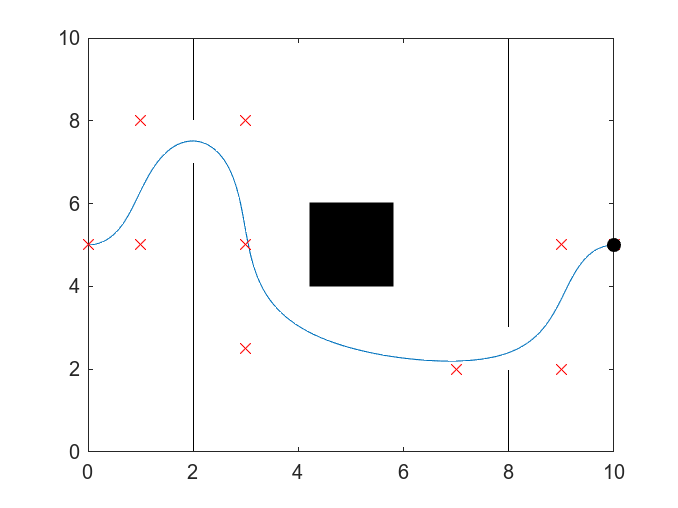

%clear
%animation speed should be pmax*pstep/20fps???? Changed between 1 and 2
%stack, need to fix this, get animations up to 4 stack, and redo NBR with
%lower sample rate to fit animation to 1000 frames
%ALL ANIMATIONS SHOULD FIT 1000 FRAMES FOR EXPORT
clear subplot
sz = size(PosMAT);
len = sz(1,1);
x = PosMAT(:,1);
y = PosMAT(:,2);
u = VelMAT(:,1);
v = VelMAT(:,2);
a = AccMAT(:,1);
b = AccMAT(:,2);
j = JerkMAT(:,1);
k = JerkMAT(:,2);
s = SnapMAT(:,1);
t = SnapMAT(:,2);
%subplot(2,1,1);
plts = cell(1,10);
plts{1,1} = plot(x, y);
hold on
scatter(targets(:,1), targets(:,2), 50, 'X', 'red');
plts{1,10} = scatter(x(1), y(1), 50, 'filled', "o", 'black');
plts{1,2} = quiver(x(1), y(1), u(1), v(1), 1, 'green');
plts{1,3} = quiver(x(1), y(1), a(1), b(1), 1, 'red');
plts{1,4} = quiver(x(1), y(1), j(1), k(1), 1, 'blue');
plts{1,5} = quiver(x(1), y(1), s(1), t(1), 1, 'black');
%Obstacles
scatter(5,5, 3000, 'square', 'filled', 'black')
scatter([2;2;2;2;2;2;2], [9;6;5;4;3;2;1], 1600, '|', 'black')
scatter([8;8;8;8;8;8;8], [9;8;7;6;5;4;1], 1600, '|', 'black')
xlim([0,10])
ylim([0,10])
hold off
%subplot(2,1,2);
pauselen = pstep*4;
for i = 1:1:round(len)
    %Update graph values
    set(plts{1,2},'XData', x(i), 'YData', y(i), 'UData', u(i), 'VData', v(i));
    set(plts{1,3},'XData', x(i), 'YData', y(i), 'UData', a(i), 'VData', b(i));
    set(plts{1,8},'XData', x(i), 'YData', y(i),'UData', j(i), 'VData', k(i));
    set(plts{1,9},'XData', x(i), 'YData', y(i),'UData', s(i), 'VData', t(i));
    set(plts{1,10},'XData', x(i), 'YData', y(i));
    pause(pauselen)
    %Draw updated graph
    drawnow limitrate;
end

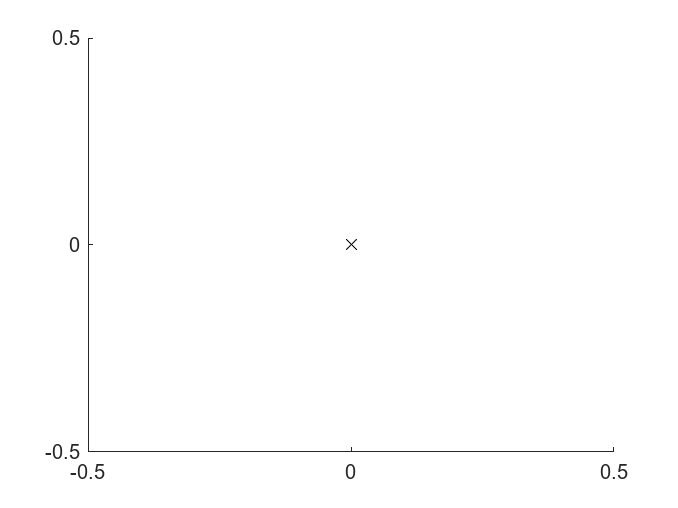

scatter(0,0, 50, 'X','black');
hold on
plts{1,6} = quiver(0, 0, u(1), v(1), 'green');
plts{1,7} = quiver(0, 0, a(1), b(1), 'red');
plts{1,8} = quiver(0, 0, j(1), k(1), 'blue');
plts{1,9} = quiver(0, 0, s(1), t(1), 'black');
xlim([-0.5, 0.5])
ylim([-0.5, 0.5])
hold off
for i = 1:1:len
    set(plts{1,6},'XData', 0, 'YData', 0,'UData', u(i), 'VData', v(i));
    set(plts{1,7},'XData', 0, 'YData', 0,'UData', a(i), 'VData', b(i));
    set(plts{1,8},'XData', 0, 'YData', 0,'UData', j(i), 'VData', k(i));
    set(plts{1,9},'XData', 0, 'YData', 0,'UData', s(i), 'VData', t(i));
    drawnow limitrate;
end

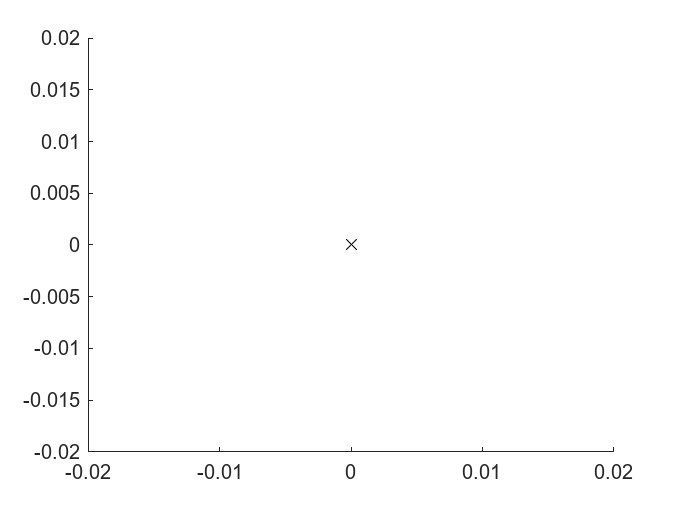

scatter(0,0, 50, 'X','black');
hold on
plts{1,8} = quiver(0, 0, j(1), k(1), 1, 'blue');
plts{1,9} = quiver(0, 0, s(1), t(1), 1, 'black');
xlim([-0.02, 0.02])
ylim([-0.02, 0.02])
hold off
for i = 1:1:len
    set(plts{1,8},'XData', 0, 'YData', 0,'UData', j(i), 'VData', k(i));
    set(plts{1,9},'XData', 0, 'YData', 0,'UData', s(i), 'VData', t(i));
    drawnow limitrate;
end